%24/02/2024 Investigation into barrier functions as a method of obstacle
%avoidance - non-functional
%Control Points
P1 = [0, 100];
P2 = [50, 50];
P3 = [100, 0];
P4 = P3;
P5 = P4;
CP = [P1, P2, P3, P4, P5];
%Knot Vector
kn1 = 0.00;
kn2 = 0.01;
kn3 = 0.02;
kn4 = 0.03;
kn5 = 30;
kn6 = 59.97;
kn7 = 59.98;
kn8 = 59.99;
kn9 = 60;
knot = [kn1, kn2, kn3, kn4, kn5, kn6, kn7, kn8, kn9];
vpmin = t4;
vpmax = t6;
%Curve Parameters
pmin = 0;
pmax = 60;
pstep = 0.01;
%Array Prealocation
stackx = [];
stacky = [];
%Obstacles
O1 = [50, 50];
O1w = 20;
O1X = [O1(1,1)+0.5*O1w, O1(1,1)-0.5*O1w];
O1Y = [O1(1,2)+0.5*O1w, O1(1,2)-0.5*O1w];
NSx = [];
SSx = [];
Sx = [];
ESy = [];
WSy = [];
Sy = [];

for p = pmin:pstep:pmax
    if p >= vpmin
        if p<=vpmax
            [SumX, SumY] = NXK4(p, knot, CP);
            stackx = [stackx; SumX];
            stacky = [stacky; SumY];
        end
    end
end
for x = O1X(1,2):step:O1X(1,1)
    NSx = [NSx; UppSqu(x, O1X,O1Y)];
    SSx = [SSx; LowSqu(x, O1X,O1Y)];
    Sx = [Sx; x];
end
for y = O1Y(1,2):step:O1Y(1,1)
    ESy = [ESy; LeftSqu(y, O1Y,O1X)];
    WSy = [WSy; RightSqu(y, O1Y,O1X)];
    Sy = [Sy; y];
end
CPx = [P1(1,1), P2(1,1), P3(1,1)];
CPy = [P1(1,2), P2(1,2), P3(1,2)];
plot(stackx, stacky)
hold on
scatter(CPx, CPy, 100, "red", "X")
%scatter(O1(1,1), O1(1,2), O1w*2*10, "black", "square", "filled")
plot(Sx, NSx)

plot(Sx, SSx)

plot(ESy, Sy)

plot(WSy, Sy)

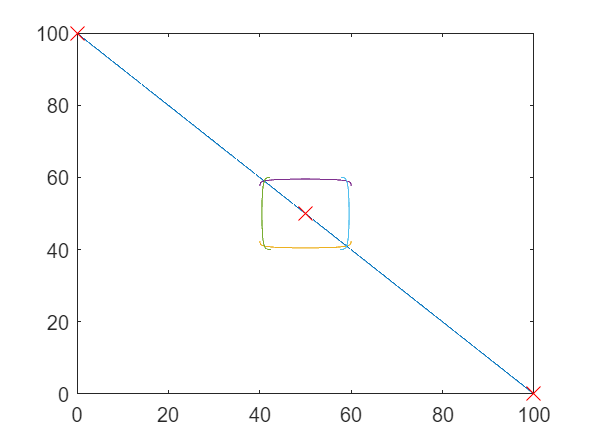

hold off

function y = UppSqu(x, O1X, O1Y)
    y = -0.1*log(O1X(1,2)-x)*log(x-(O1X(1,1))) + O1Y(1,2);
end
function y = LowSqu(x, O1X, O1Y)
    y = 0.1*log(O1X(1,2)-x)*log(x-O1X(1,1)) + O1Y(1,1);
end
function x = LeftSqu(y, O1Y, O1X)
    x = -0.1*log(O1Y(1,2)-y)*log(y-(O1Y(1,1))) + O1X(1,2);
end
function x = RightSqu(y, O1Y, O1X)
    x = 0.1*log(O1Y(1,2)-y)*log(y-(O1Y(1,1))) + O1X(1,1);
end
function [SumNPx, SumNPy] = NXK4(p, knot, CP)

    P1(1,1) = CP(1,1);
    P1(1,2) = CP(1,2);
    P2(1,1) = CP(1,3);
    P2(1,2) = CP(1,4);
    P3(1,1) = CP(1,5);
    P3(1,2) = CP(1,6);
    P4(1,1) = CP(1,7);
    P4(1,2) = CP(1,8);
    P5(1,1) = CP(1,9);
    P5(1,2) = CP(1,10);

    p1 = knot(1,1);
    p2 = knot(1,2);
    p3 = knot(1,3);
    p4 = knot(1,4);
    p5 = knot(1,5);
    p6 = knot(1,6);
    p7 = knot(1,7);
    p8 = knot(1,8);
    p9 = knot(1,9);

    if (p1<=p)
        if (p<p2)
            N1k1 = 1;
        else
            N1k1 = 0;
        end
    else
        N1k1 = 0;
    end
    if (p2<=p)
        if (p<p3)
            N2k1 = 1;
        else
            N2k1 = 0;
        end
    else
        N2k1 = 0;
    end
    if (p3<=p)
        if (p<p4)
            N3k1 = 1;
        else
            N3k1= 0;
        end
    else
        N3k1 = 0;
    end
    if (p4<=p)
        if (p<p5)
            N4k1 = 1;
        else
            N4k1 = 0;
        end
    else
        N4k1 = 0;
    end
    if (p5<=p)
        if (p<p6)
            N5k1 = 1;
        else
            N5k1 = 0;
        end
    else
        N5k1 = 0;
    end
    if (p6<=p)
        if (p<p7)
            N6k1 = 1;
        else
            N6k1 = 0;
        end
    else
        N6k1 = 0;
    end
    if (p7<=p)
        if (p<p8)
            N7k1 = 1;
        else
            N7k1 = 0;
        end
    else
        N7k1 = 0;
    end
    if (p8<=p)
        if (p<p9)
            N8k1 = 1;
        else
            N8k1 = 0;
        end
    else
        N8k1 = 0;
    end

    N1k2 = ((p-p1)/(p2-p1))*N1k1 + ((p3-p)/(p3-p2))*N2k1;
    N2k2 = ((p-p2)/(p3-p2))*N2k1 + ((p4-p)/(p4-p3))*N3k1;
    N3k2 = ((p-p3)/(p4-p3))*N3k1 + ((p5-p)/(p5-p4))*N4k1;
    N4k2 = ((p-p4)/(p5-p4))*N4k1 + ((p6-p)/(p6-p5))*N5k1;
    N5k2 = ((p-p5)/(p6-p5))*N5k1 + ((p7-p)/(p7-p6))*N6k1;
    N6k2 = ((p-p6)/(p7-p6))*N6k1 + ((p8-p)/(p8-p7))*N7k1;
    N7k2 = ((p-p7)/(p8-p7))*N7k1 + ((p9-p)/(p9-p8))*N8k1;

    N1k3 = ((p-p1)/(p3-p1))*N1k2 + ((p4-p)/(p4-p2))*N2k2;
    N2k3 = ((p-p2)/(p4-p2))*N2k2 + ((p5-p)/(p5-p3))*N3k2;
    N3k3 = ((p-p3)/(p5-p3))*N3k2 + ((p6-p)/(p6-p4))*N4k2;
    N4k3 = ((p-p4)/(p6-p4))*N4k2 + ((p7-p)/(p7-p5))*N5k2;
    N5k3 = ((p-p5)/(p7-p5))*N5k2 + ((p8-p)/(p8-p6))*N6k2;
    N6k3 = ((p-p6)/(p8-p6))*N6k2 + ((p9-p)/(p9-p7))*N7k2;

    N1k4 = ((p-p1)/(p4-p1))*N1k3 + ((p5-p)/(p5-p2))*N2k3;
    N2k4 = ((p-p2)/(p5-p2))*N2k3 + ((p6-p)/(p6-p3))*N3k3;
    N3k4 = ((p-p3)/(p6-p3))*N3k3 + ((p7-p)/(p7-p4))*N4k3;
    N4k4 = ((p-p4)/(p7-p4))*N4k3 + ((p8-p)/(p8-p5))*N5k3;
    N5k4 = ((p-p5)/(p8-p5))*N5k3 + ((p9-p)/(p9-p6))*N6k3;

    SumNPx = N1k4*P1(1,1) + N2k4*P2(1,1) + N3k4*P3(1,1) + N4k4*P4(1,1) + N5k4*P5(1,1);
    SumNPy = N1k4*P1(1,2) + N2k4*P2(1,2) + N3k4*P3(1,2) + N4k4*P4(1,2) + N5k4*P5(1,2);
end